# Procedure 1 for Closed Koopman System with scaling

clear; close all; clc;
set(0,'DefaultLineLineWidth',2.5) 
set(0,'defaultfigurecolor',[1 1 1])

## Dynamics

## 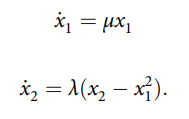

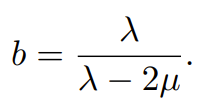

mu=0.8; 
lambda =-1.9;
f = @(t, x)[mu*x(1,:);  lambda*(x(2,:)-x(1,:).^2)];

## Linearization

n=2; % dimension
x = sym('x',[n;1]);
x0 = [0;0];

A = double(subs(jacobian(f(0,x),x),x,x0)); 
B = [1; 1];
%linear eigenfunctions realization from complex eigenfunctions
[~,D1,W1] = eig(A);
[W, D] = cdf2rdf(W1, D1);

## Selet basis functions to approximate h(x)

x1 = sym('x',[n,1]);
order = 2; %order poly

[Psi, DPsi] = monomial_basis(order, n);
Psi = Psi(n+1:end); %remove linear part
Nbs = length(Psi);
DPsi = jacobian(Psi,x1);

Psi = matlabFunction(Psi,'Vars',{x1});
DPsi = matlabFunction(DPsi,'Vars',{x1});

## Parameters setup and sclaing function

Dom = [-5 5]; %Domain
domain = Dom(2)-Dom(1);

## Collect random initial conditions

numICs = 1e4; %initial coditions
X = rand(n,numICs)*2*Dom(2) - Dom(2); %sample initial conditions

## Scale the F(z) and Ez data points

F_z = f(0, X);
F_z_scaled = F_z./domain;

E = A;
E_z = E*X;
E_z_scaled = E_z./domain;

X_scaled = X./domain;

## Solve the least squares problem to estimate U scaled

G_z = Psi(X_scaled);

for i=1:size(X_scaled,2)
    Df_z(:,i) = DPsi(X_scaled(:,i))*F_z_scaled(:,i);
end

% YALMIP 
U_scaled = sdpvar(n,Nbs);
Objective =  norm(U_scaled*Df_z + F_z_scaled - E*U_scaled*G_z - E_z_scaled, 'fro'); 
Constraints = [];
opt = sdpsettings('solver','gurobi','verbose',1,'cachesolvers',1);
sol = optimize(Constraints,Objective,opt);

Set parameter Username
Academic license - for non-commercial use only - expires 2023-02-12
Gurobi Optimizer version 9.5.0 build v9.5.0rc5 (win64)
Thread count: 10 physical cores, 20 logical processors, using up to 20 threads
Optimize a model with 20001 rows, 20008 columns and 80002 nonzeros
Model fingerprint: 0x8b02ad4f
Model has 1 quadratic constraint
Coefficient statistics:
  Matrix range     [7e-12, 6e+00]
  QMatrix range    [1e+00, 1e+00]
  Objective range  [1e+00, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [2e-10, 5e+00]
Presolve removed 1 rows and 1 columns
Presolve time: 0.03s
Presolved: 20000 rows, 20007 columns, 80000 nonzeros
Presolved model has 1 second-order cone constraint
Ordering time: 0.00s

Barrier statistics:
 Dense cols : 7
 Free vars  : 6
 AA' NZ     : 8.000e+04
 Factor NZ  : 1.000e+05 (roughly 17 MB of memory)
 Factor Ops : 5.001e+05 (less than 1 second per iteration)
 Threads    : 1

                  Objective                Residual
Iter       P

U_scaled = value(U_scaled)

U_scaled =          0         0         0
    0.0000    0.0000   -5.4286


## Map U back to the origonal domain

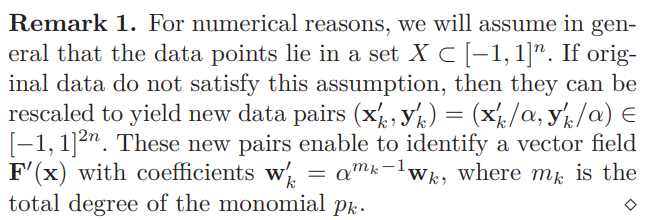

Mauroy, A., & Goncalves, J. (2019). Koopman-based lifting techniques for nonlinear systems identification. *IEEE Transactions on Automatic Control. *(https://arxiv.org/pdf/1709.02003.pdf) 

monomial_degrees = polynomialDegree(Psi(x));

U = [];
alpha = domain;

for k = 1:size(monomial_degrees,1)
    m_k = monomial_degrees(k);
    unscale = alpha^(m_k-1);
    unscale_factor = [unscale;unscale];
    U(:,k) = U_scaled(:,k)./unscale_factor;
end
U

U =          0         0         0
    0.0000    0.0000   -0.5429


## Eigenfunctions of the original system

% nonlinear eigenfuncitons without scaling
Phi = @(x) W'*x + W'*U*Psi(x);
DPhi = @(x) W' + W'*U*DPsi(x);

## Sanity Check for principle eignefunctions

x_eval = [1.2;-1.3];
b = lambda/(2*mu-lambda)

b = -0.5429

## Evaluating analytical eigenfuction

Phi_analytical = @(x)[x(1); x(2)+b*x(1)^2];
Phi_analytical(x_eval)

ans =     1.2000
   -2.0817


## Evaluating eigenfuction approximated from data

Phi(x_eval)

ans =    -2.0817
    1.2000


## LQR controller

Q = 1*eye(2,2); %cost on states
R_lqr = 1;
[K,P,CLP] = lqr(A,B,Q,R_lqr);
uLQR = @(x) -K*(x);

## HJ-Koopman Controller:

Where,

Compare matlab's Riccati equation for LQR, we get R_koopman = B_tranpose*inv(R_lqr)*B

R_Koopman = inv(R_lqr).*B*B';
hat_R = W'*(R_Koopman)*W;
W1_inv = inv(W);
hat_Q = W1_inv*Q*W1_inv';
L = are(D,hat_R,hat_Q);

uKoop=@(x) -inv(R_lqr).*Phi(x)'*L*DPhi(x)*B; 

## Sanity Check for linear basis

## P should match with L1

L1 = W*L*W'

L1 =     2.3586   -0.1737
   -0.1737    0.2611


P

P =     2.3586   -0.1737
   -0.1737    0.2611


## Simulation

(change x_initial to simulate response of different initial conditions and plot)

f_u = @(t,x,u)[f(t,x)+B*u];

tspan = 0:0.01:5;

options = odeset('RelTol',1e-9,'AbsTol',1e-300);
x_initial = [10;10]; %unstable for u_koop without scaling

%LQR
[tspan, xLQR] = ode45(@(t,x)f_u(t, x, uLQR(x)), tspan, x_initial, options);

if(abs(xLQR(end,1)) && abs(xLQR(end,2)) <=1e-3)
    disp('LQR succuess')
else
    disp('LQR failed')
end

LQR failed


[tspan1, x_Koop] = ode45(@(t,x)f_u(t, x, uKoop(x)), tspan, x_initial, options);
if(abs(x_Koop(end,1)) && abs(x_Koop(end,2)) <=1e-3)
    disp('HJK succuess')
else
    disp('HJK failed')
end

HJK failed


## Plots

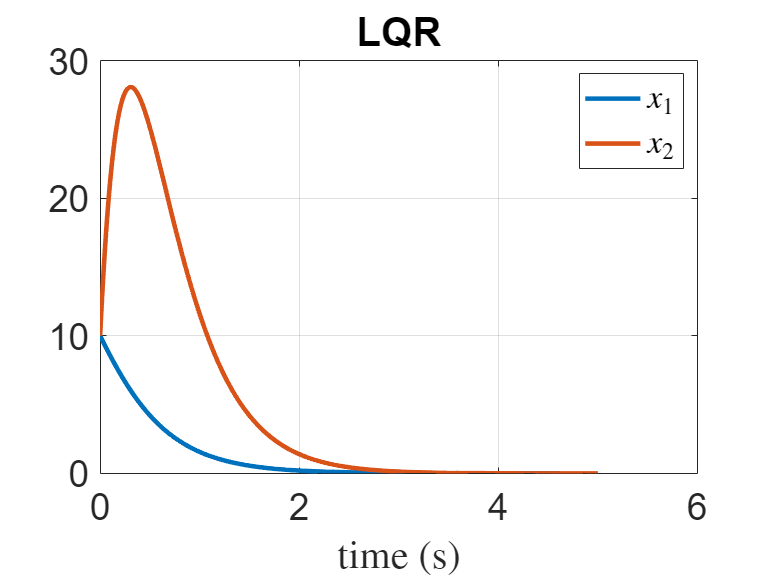

close all
figure(1)
%subplot(2,2,1)
plot(tspan, xLQR)
grid on;
title('LQR')
xlabel('time (s) ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$x_1$', '$x_2$');
set(LEG,'interpreter','latex')

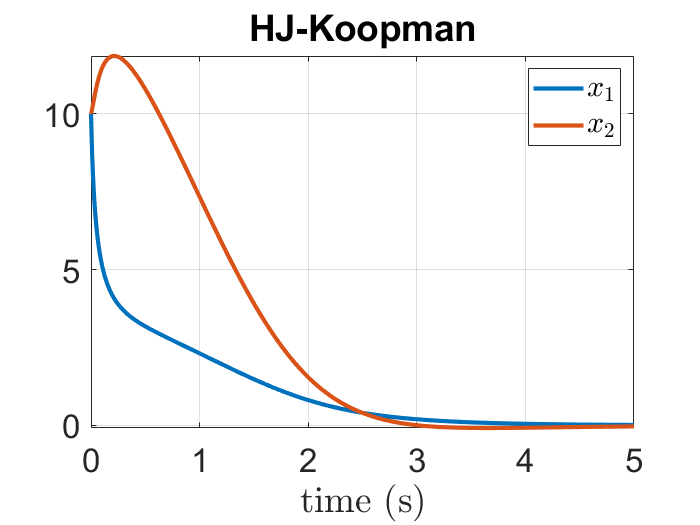

figure()
plot(tspan1, x_Koop)
grid on;
title('HJ-Koopman')
xlabel('time (s)','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$x_1$', '$x_2$');
set(LEG,'interpreter','latex')

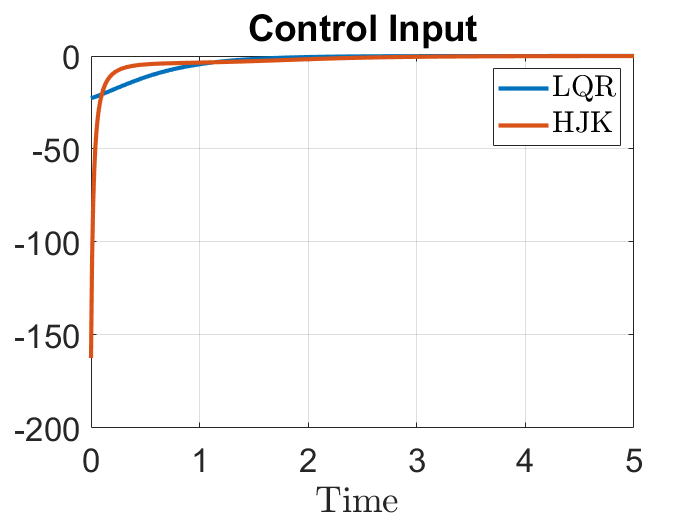

%set(LEG,'interpreter','latex')
figure(3)
%subplot(2,2,3)
U_Lqr =zeros(size(xLQR,1),1);
U_Koop = zeros(size(xLQR,1),1);

for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) = uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan, U_Koop)
grid on;
title('Input')
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

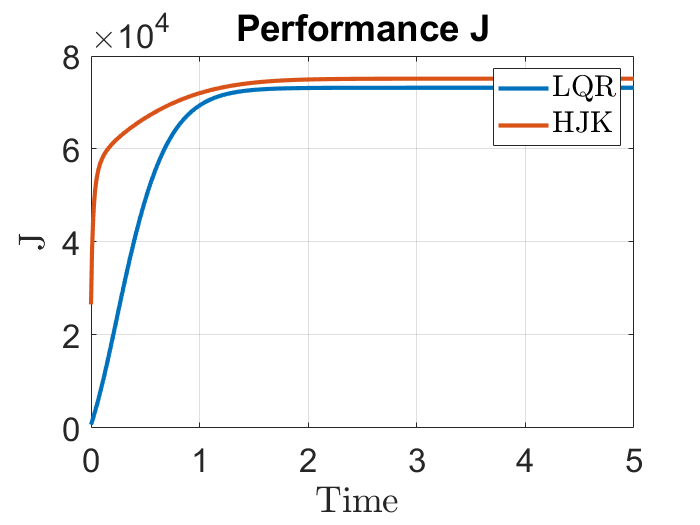

figure(4)
%subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Performance J')
set(gca,'fontsize',20)
LEG =legend('LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

## Combined Plots

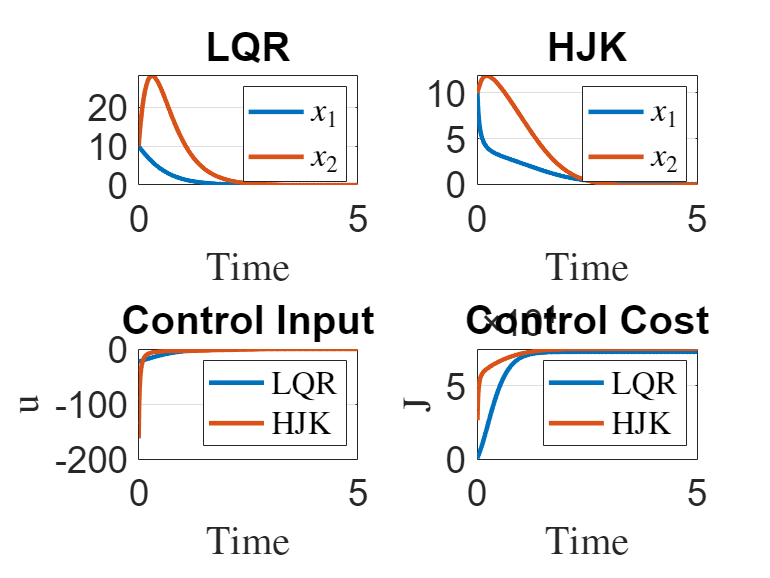

close all  
figure()
subplot(2,2,1)
plot(tspan1, xLQR)
grid on; hold on;
%legend('x_1', 'x_2');xlabel('Time')
title('LQR')
xlabel('Time ','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$x_1$', '$x_2$');
set(LEG,'interpreter','latex')

subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJK')
xlabel('Time','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$x_1$', '$x_2$');
set(LEG,'interpreter','latex')

subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
ylabel('u','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 +U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Control Cost')
set(gca,'fontsize',20)
LEG =legend('LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

## Monomial Basis

function [Psi, DPsi] = monomial_basis(deg, dim)
%  [Psi, DPsi] = monomial_basis(deg, dim) returns a monomial basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   deg = degree of monomial
%   dim = number of states
k = linspace(2, deg, deg-1);
d = dim;

if (deg == 0)
    Psi = 0;
    for i=1:dim-1
        Psi = [Psi 0];
    end
    DPsi = zeros(dim,dim);
    Psi = Psi';
    
else

    x=sym('x',[d,1]);
    assume(x,'real')
    
    Psi = [x.'];
    for i=1:size(k,2)
        m = nchoosek(k(i)+d-1,d-1); 
        dividers = [zeros(m,1),nchoosek((1:(k(i)+d-1))',d-1),ones(m,1)*(k(i)+d)]; 
        a = diff(dividers,1,2)-1;
        for i = 1:size(a,1)
            Psi = [Psi prod(x.' .^ a(i,:))];
        end
    end
    DPsi = jacobian(Psi,x);
    Psi = Psi';

end

end

## Bernstein Basis

function [Psi,DPsi] = bernstein_basis(order, dim, scale)
%  [Psi, DPsi] = bernstein_basis(deg, dim,scale=0) returns a bernstein basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   order = order of bernstein polynomials being fit
%   dim = number of states

if nargin<3
  scale = 0;
end

x=sym('x',[dim,1]);
assume(x,'real')
Psi = [];

if(order==0)
    Psi = 1;
end

for i = 0:order
    m = nchoosek(order,i);
    for j = 1:dim
        %Psi = [Psi; m.*((x(j)+1).^i * (-x(j)).^(order-i))];
        %scale to -2pi to 2pi
        Psi = [Psi; m.*((x(j)+scale).^i * (1-scale-x(j)).^(order-i))];
    end
end

DPsi = jacobian(Psi,x);

end
